Get the data sample along with other aspects used in this experiment:

it's name for display, and the dimensions to reduce to

% copied from data_set_info
% dataSeriesShortNames = [
%     "euc30", "euc30gauss",...
%     "glove", "fc6",...
%     "fc6relu", "sift",...
%     "mfGistJsd", "euc500",...
%     "gloveCos", "euc100"];


clear variables;

dataSeriesId = 1; %indexes into an array like the one above, just gets the names in case anything goes nastily wrong!
[shortname,fullname] = data_set_info(dataSeriesId);

data = get_small_data_set( shortname );

[shep_dim, red_dims] = data_set_misc_info( shortname );


grab a couple of thousand random values from the data set into two separate collections, one to build the projection (witnesses) and other to project based on that projection

witnessSize = 2000;
dataSize = 1000;

randIds = getRandomIds(witnessSize + dataSize, size(data,1));

witnesses = data(randIds(1:witnessSize),:);
data = data(randIds(witnessSize + 1 : witnessSize + dataSize),:);

clear randIds;

Now we want to plot various quality metrics against reduction dimension...


%functions are in DR measurement folder
metricNames = ["Kruskal","Spearman Rho","Sammon","Quadratic Loss"];
measures{1} = @kruskal;
measures{2} = @spearman_rho;
measures{3} = @sammon;
measures{4} = @quadratic_loss;



% plotDimensions are returned with dataset
pcaMeasures = zeros(4,size(red_dims,2));
zenMeasures = zeros(4,size(red_dims,2));
mdsMeasures = zeros(4,size(red_dims,2));
rpMeasures = zeros(4,size(red_dims,2));

%this is a bit (a lot) quicker to use than a different high level projection
%for each loop instatiation
coeff = pca(witnesses);

for i = 1 : size(red_dims,2)
    projDim = red_dims(i);
    disp(strcat("projecting to ", num2str(projDim), " dimensions"));
    
    nsimpP = NsimpProjection(witnesses,projDim,@euc);
    % from some sets, 1000 witnesses for MDS is really intractable...
    % so this could be reduced to eg 500 for eg MF fc6 data
    % this makes no discernable difference and will actually terminate!
    mdsP = MdsProjection(witnesses(1:1000,:),projDim);

    rpP = RandomProjection(size(data,2),projDim);
    
    nsimpProj = zeros(size(data,1),projDim);
%     mdsProj = zeros(size(data,1),projDim);
%     rProj = zeros(size(data,1),projDim);
    
    pcaProj = data * coeff(:,1:projDim);
    mdsProj = mdsP.project(data);
    rProj = rpP.project(data);
    for j = 1 : size(data,1)
        nsimpProj(j,:) = nsimpP.project(data(j,:));
    end
    
    pcaDists = pdist(pcaProj);
    zenDists = pdist(nsimpProj,@zen);
    mdsDists = pdist(mdsProj);
    rpDists = pdist(rProj);
    
    dataDists = pdist( data );
    
    for m = 1 : 4
        pcaMeasures(m,i) = measures{m}(dataDists,pcaDists);
        zenMeasures(m,i) = measures{m}(dataDists,zenDists);
        mdsMeasures(m,i) = measures{m}(dataDists,mdsDists);
        rpMeasures(m,i) = measures{m}(dataDists,rpDists);
    end
end

    30

    25

    20

    16

    12

    10

     8

     5

     3

     2



% invert the stress measures so 1 is best, 0 is worst
% do this just once!
zenMeasures(1,:) = 1 - zenMeasures(1,:);
pcaMeasures(1,:) = 1 - pcaMeasures(1,:);
mdsMeasures(1,:) = 1 - mdsMeasures(1,:);
rpMeasures(1,:) = 1 - rpMeasures(1,:);
zenMeasures(3,:) = 1 - zenMeasures(3,:);
pcaMeasures(3,:) = 1 - pcaMeasures(3,:);
mdsMeasures(3,:) = 1 - mdsMeasures(3,:);
rpMeasures(3,:) = 1 - rpMeasures(3,:);


plot charts for: Kruskal stress, Spearman Rho, Sammon Stress, and quadratic loss

m = -30

x = 6

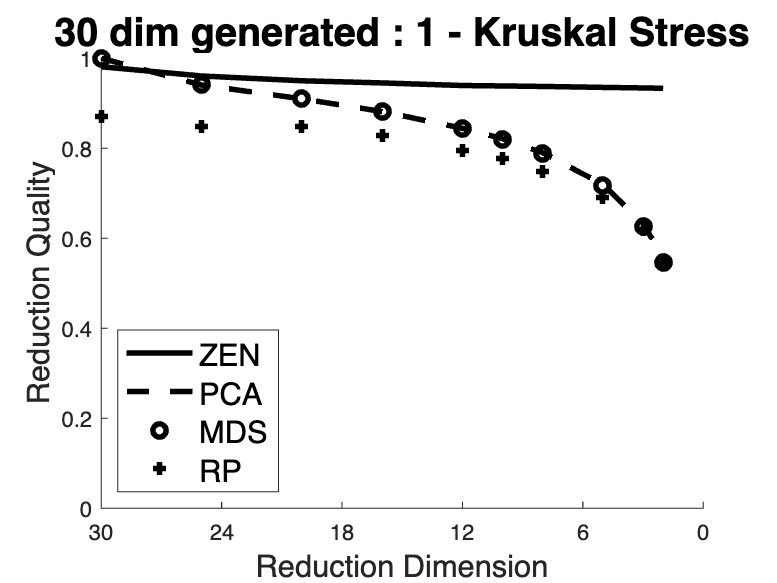


plotChart(red_dims,zenMeasures,pcaMeasures,mdsMeasures,rpMeasures,fullname,1);

m = -30

x = 6

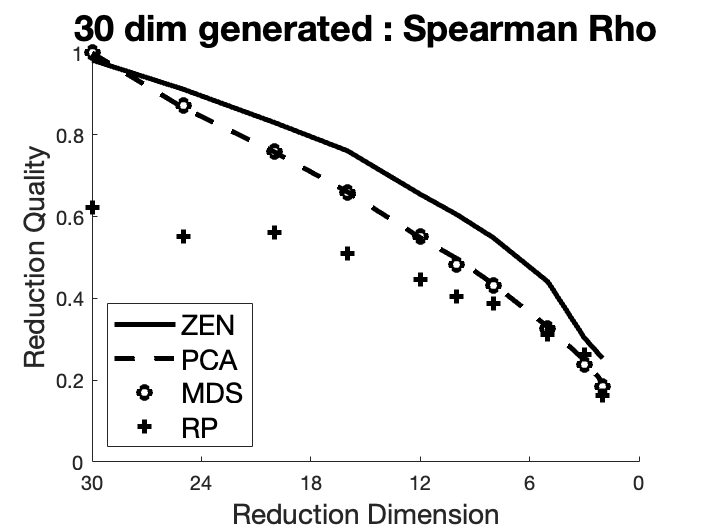

plotChart(red_dims,zenMeasures,pcaMeasures,mdsMeasures,rpMeasures,fullname,2);

m = -30

x = 6

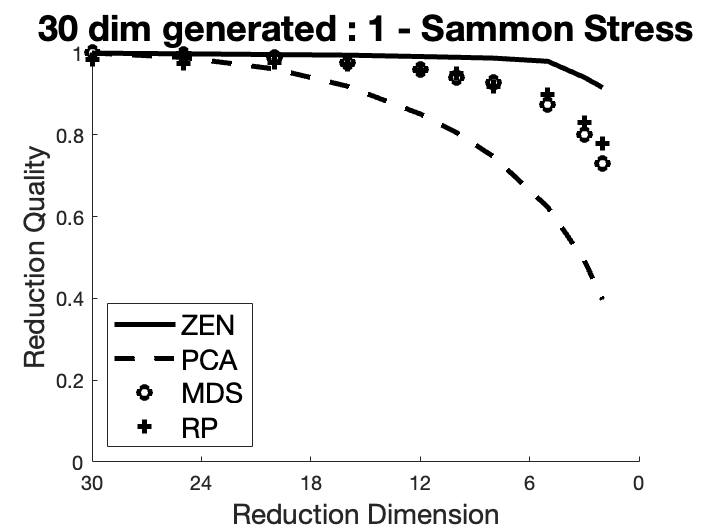

plotChart(red_dims,zenMeasures,pcaMeasures,mdsMeasures,rpMeasures,fullname,3);

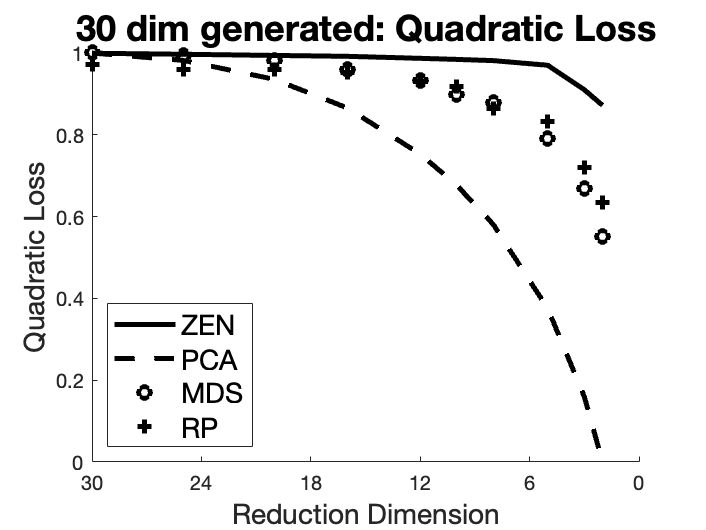

plotQuadLoss(red_dims,zenMeasures,pcaMeasures,mdsMeasures,rpMeasures,fullname);